# Analog Modulation FM

# (Autónoma)

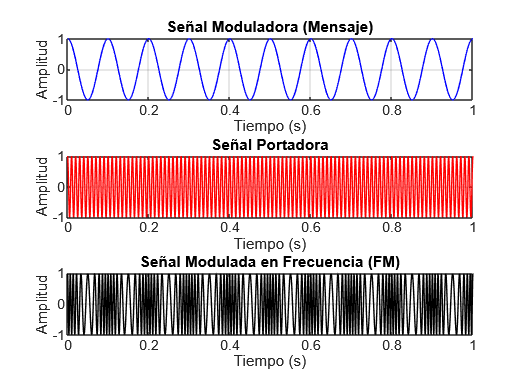

%% Modulación en Frecuencia (FM) en MATLAB
% Descripción: Este código genera y grafica una señal moduladora (mensaje),
% una señal portadora y la señal modulada en frecuencia (FM).

%% Parámetros de la señal
fs = 10000; % Frecuencia de muestreo (Hz)
duration = 1; % Duración de la señal en segundos
t = 0:1/fs:duration; % Vector de tiempo

Am = 1; % Amplitud de la señal moduladora
fm = 10; % Frecuencia de la señal moduladora (Hz)
message = Am * cos(2 * pi * fm * t); % Señal moduladora

Ac = 1; % Amplitud de la portadora
fc = 100; % Frecuencia de la portadora (Hz)
carrier = Ac * cos(2 * pi * fc * t); % Señal portadora

kf = 50; % Índice de desviación de frecuencia (Hz/V)
integral_message = cumsum(message) * (1/fs); % Integral de la señal moduladora
fm_signal = Ac * cos(2 * pi * fc * t + 2 * pi * kf * integral_message); % Señal FM

%% Gráficas
figure;

subplot(3,1,1);
plot(t, message, 'b');
grid on;
title('Señal Moduladora (Mensaje)');
xlabel('Tiempo (s)');
ylabel('Amplitud');

subplot(3,1,2);
plot(t, carrier, 'r');
grid on;
title('Señal Portadora');
xlabel('Tiempo (s)');
ylabel('Amplitud');

subplot(3,1,3);
plot(t, fm_signal, 'k');
grid on;
title('Señal Modulada en Frecuencia (FM)');
xlabel('Tiempo (s)');
ylabel('Amplitud');